clear
x = [1414;28;112;41;404;493;736;812;1300;1885;2940;125;284;207];
y = [663;7360;3810;7007;1470;1098;998;824;700;523;439;5400;2340;2400];

fit= fit(x,y,'power1')

fit =      General model Power1:
     fit(x) = a*x^b
     Coefficients (with 95% confidence bounds):
       a =   5.197e+04  (2.661e+04, 7.733e+04)
       b =     -0.5574  (-0.6737, -0.441)

a=-20

a = -20

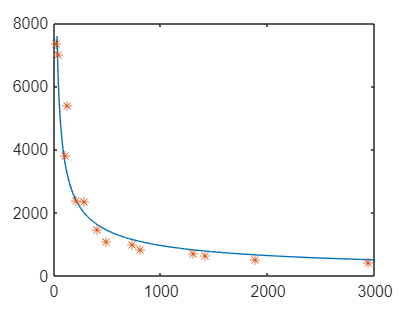


x1= [28:3000];
y1 = fit.a*x1.^(fit.b+a/1000);

plot(x1,y1);

% xlim ([0,1000])
hold on 
plot (x,y,"*");

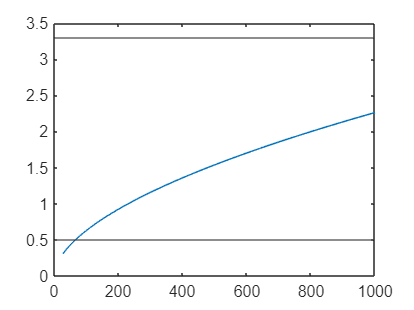


E= -5;
R0= 0.5 *10^3;
vo= -E*R0/fit.a *x1.^(-fit.b);
figure;
plot (x1,vo);
xlim ([0,1000])
yline(3.3)
yline(0.5)

Circuito B

vb= 0.1;
R0= 27 *10^3;
vo= vb+vb*R0./(fit.a *x1.^(fit.b+a/1000));
figure;
plot (x1,vo);
xlim ([0,1000])
yline(3)
yline(0.5)

error linealización

linfitb=polyfit(x1(1:1000),vo(1:1000),1)

linfitb =     0.0023    0.7392


lin = linfitb(1)*x1+linfitb(2)-0.1

lin =     0.7034    0.7057    0.7080    0.7103    0.7126    0.7149    0.7172    0.7195    0.7218    0.7241    0.7264    0.7287    0.7309    0.7332    0.7355    0.7378    0.7401    0.7424    0.7447    0.7470    0.7493    0.7516    0.7539    0.7562    0.7585    0.7608    0.7631    0.7654    0.7676    0.7699    0.7722    0.7745    0.7768    0.7791    0.7814    0.7837    0.7860    0.7883    0.7906    0.7929    0.7952    0.7975    0.7998    0.8021    0.8043    0.8066    0.8089    0.8112    0.8135    0.8158


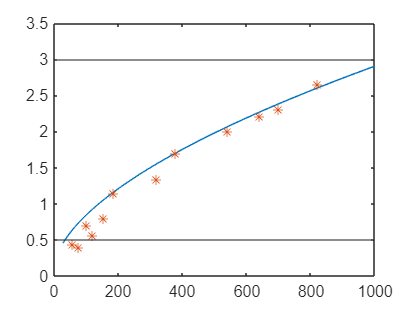

hold on
% plot(x1,lin)

xmedida = [58;75;102;120;154;186;640;700;540;320;820;1100;380];
ymedida = [0.43;0.4;0.7;0.56;0.8;1.14;2.2;2.3;2;1.33;2.65;3.2;1.7];
plot(xmedida, ymedida,"*")

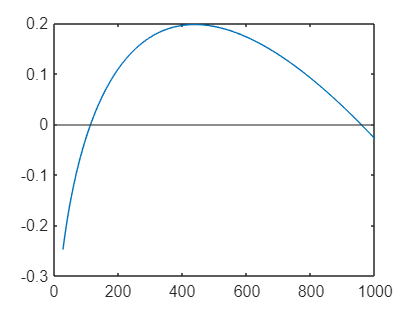

figure
plot(x1,vo-lin)
yline(0)

xlim ([0,1000])

R=1000

R = 1000

B= 5000

B = 5000

x=[0:0.1:5]

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


figure()
y=R*exp(B./(x+273.15)-B./273.15)

y = 1.0e+03 *

    1.0000    0.9933    0.9867    0.9801    0.9736    0.9671    0.9607    0.9543    0.9479    0.9417    0.9354    0.9292    0.9231    0.9169    0.9109    0.9049    0.8989    0.8930    0.8871    0.8812    0.8754    0.8697    0.8639    0.8583    0.8526    0.8470    0.8415    0.8360    0.8305    0.8251    0.8197    0.8143    0.8090    0.8037    0.7985    0.7933    0.7881    0.7830    0.7779    0.7728    0.7678    0.7628    0.7579    0.7530    0.7481    0.7433    0.7385    0.7337    0.7290    0.7243


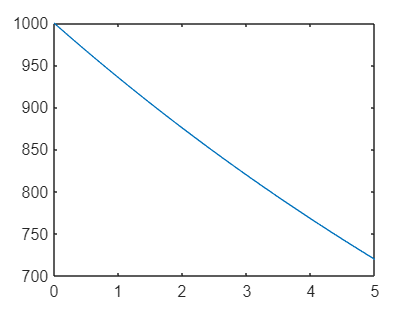

plot(x,y)



% 
% vin 3.3
% Rl = 
% R =4700
